SubjectNr = "001";

dataString = "Data\sleep-cassette\SC4" + SubjectNr + "E0-PSG.edf";
annotationsString = "Data\sleep-cassette\SC4" + SubjectNr + "EC-Hypnogram.edf";

data = edfread(dataString)

data = 2650×7 timetable
    Record Time       EEGFpz_Cz          EEGPz_Oz         EOGHorizontal     RespOro_nasal    EMGSubmental      TempRectal       EventMarker 
    ___________    _______________    _______________    _______________    _____________    _____________    _____________    _____________

    0 sec          {3000×1 double}    {3000×1 double}    {3000×1 double}    {30×1 double}    {30×1 double}    {30×1 double}    {30×1 double}
    30 sec         {3000×1 double}    {3000×1 double}    {3000×1 double}    {30×1 double}    {30×1 double}    {30×1 double}    {30×1 double}
    60 sec         {3000×1 double}    {3000×1 double}    {3000×1 double}    {30×1 double

Annotations = edfinfo(annotationsString);

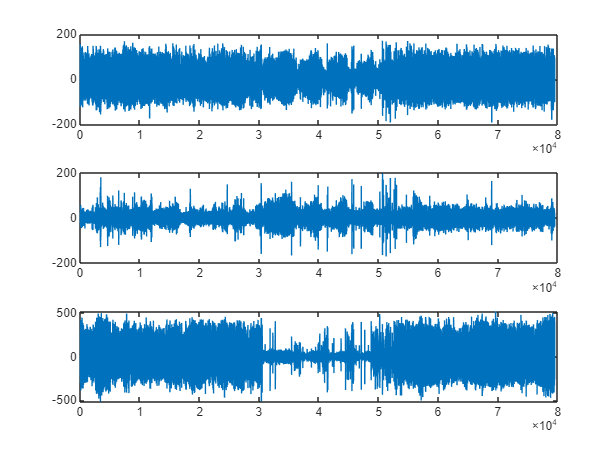

info = edfinfo(dataString);
Fs = 100;

stateSeqLen = 30;
seqLen = 3000;
seqTime = 30;

numSeqs = 2650;

m = 1e6;
n = 3;

stages = Annotations.Annotations.(1);
stages(stages == "Sleep stage W") = 1;
stages(stages == "Sleep stage 1") = 2;
stages(stages == "Sleep stage 2") = 3;
stages(stages == "Sleep stage 3") = 4;
stages(stages == "Sleep stage 4") = 4;
stages(stages == "Sleep stage R") = 5;

stages = double(stages) + 1;

onsets = Annotations.Annotations.Onset;
total_duration = seconds(Annotations.Annotations.Onset(end));
expandedStages = zeros(1, total_duration);

durations = diff([onsets; total_duration]);

% Fill in expandedStages
for i = 1:length(stages)
    start_idx = seconds(onsets(i)) + 1; 
    end_idx = min(start_idx + seconds(durations(i)) - 1, total_duration);
    expandedStages(start_idx:end_idx) = stages(i);
end



X = zeros(n, numSeqs*seqLen);
t = linspace(0, seqTime*numSeqs, seqLen*numSeqs);

figure()
for i = 1:n
    for j = 1:numSeqs
        X(i, 1+(j-1)*seqLen:j*seqLen) = data.(i){j};
    end
    subplot(n, 1, i);
    plot(t, X(i, :));
end

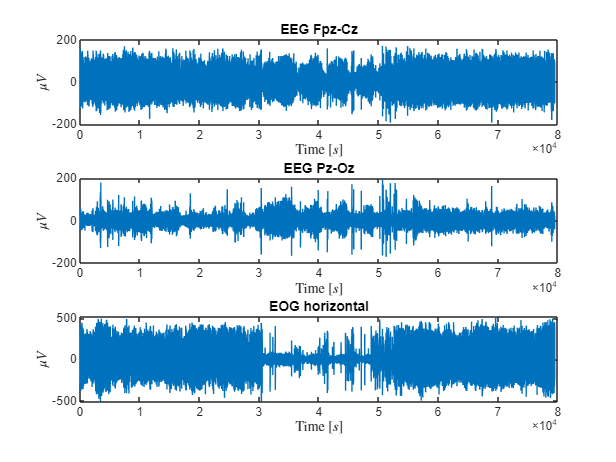

figure()
for i = 1:3
    subplot(3, 1, i);
    plot(t, X(i, :));
    title(info.SignalLabels{i});
    ylabel('$\mu V$', 'Interpreter','latex');
    xlabel('Time [$s$]', 'Interpreter','latex')
end

freqBands = [0.5 4.5; 
            4.5 8.5; 
            8.5 11.5; 
            11.5 15.5; 
            15.5 30]; % 'Delta', 'Theta', 'Alpha', 'Sigma', 'Beta'
bandNames = {'Delta', 'Theta', 'Alpha', 'Sigma', 'Beta'};

% numFreqRanges = 1;
% minfreq = 0.1;
% maxfreq = 30;
% freqrange = exp(linspace(log(minfreq),log(maxfreq), numFreqRanges + 1))';
% freqBands = [freqrange(1:end-1) freqrange(2:end)];
% 
% 
% freqBands = [0.1 4; 4 8; 8 12; 12 30]; % Delta, Theta, Alpha, Beta
% bandNames = {'Delta', 'Theta', 'Alpha', 'Beta'};

% windowSize = 2*Fs; 


windowSize = 2 * Fs;  % 2-second window
overlap = 1 * Fs;     % 1-second overlap
nChannels = size(X, 1);
nBands = size(freqBands, 1);
seq = [];  

for ch = 1:nChannels
    x = X(ch, :);
    for b = 1:nBands
        % Bandpass filter
        f1 = freqBands(b, 1);
        f2 = freqBands(b, 2);
        bpFilt = designfilt('bandpassiir','FilterOrder',4, ...
            'HalfPowerFrequency1',f1,'HalfPowerFrequency2',f2, ...
            'SampleRate',Fs);

        xFilt = filtfilt(bpFilt, x);

        % Power calculation using RMS or bandpower
        [~, ~, ~, P] = spectrogram(xFilt, windowSize, overlap, [], Fs);
        bandPower = mean(abs(P).^2, 1)';  % Average power over time
        seq = [seq; bandPower'];
    end
end

% Optionally, take log:
seq = log(seq + eps);



filWinSz = 2;
den = (1/filWinSz)*ones(1,filWinSz);
numer = 1;

if(filWinSz > 0)
    for i = 1:n
        seq(i, :) = filter(den,numer,seq(i, :)); % Moving average filter
    end
end

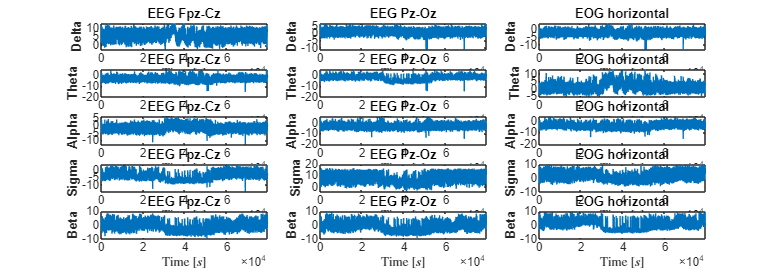






plotsize = length(seq);
figure('Renderer', 'painters', 'Position', [10 10 2000 700])
num = 1;
for b = 1:nBands
    for ch = 1:nChannels
        subplot(nBands, nChannels, num);
        plot(1:plotsize, seq(num, 1:plotsize))
        title(info.SignalLabels{ch})

        xlabel('Time [$s$]', 'Interpreter','latex')
        
        if(nBands == length(bandNames))
            ylabel(bandNames{b}, "FontWeight","bold")
        end
        num = num + 1;
    end
end

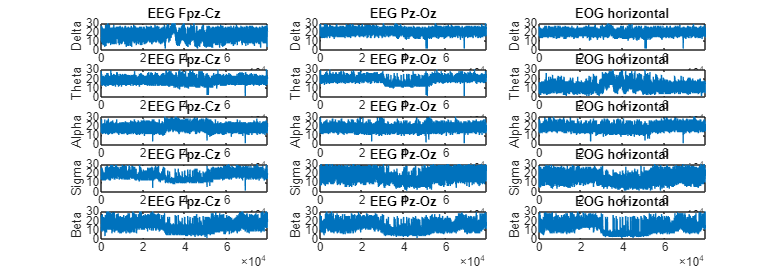

k = 5;
d = 30;
n = nBands*nChannels;


[seq, mins, maxs] = NormalizeData(seq);
[disc_seq,~] = discretize(seq, d);



plotsize = length(seq);
figure('Renderer', 'painters', 'Position', [10 10 2000 700])
num = 1;
for b = 1:nBands
    for ch = 1:nChannels
        subplot(nBands, nChannels, num);
        plot(1:plotsize, disc_seq(num, 1:plotsize))
        title(info.SignalLabels{ch})
        
        if(nBands == length(bandNames))
            ylabel(bandNames{b})
        end
        num = num + 1;
    end
end


P3 = cell(n,1);
for ii = 1:n
    P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
end





alpha = 0.05;
rho = 0.9;

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-15;
cpd_options.th_relerr = 3e-5;
cpd_options.epsilon = 1/10;
cpd_options.ConvergeVars = false;


[T_hat, O_hats, pi_hat, cpd_output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);


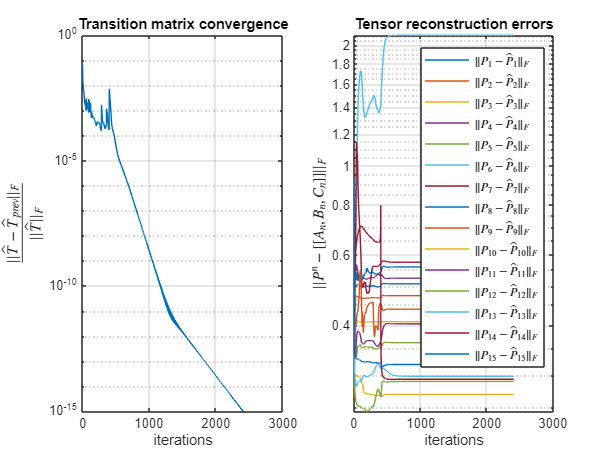


figure()
subplot(1, 2, 1);
semilogy(cpd_output.tconv);
title("Transition matrix convergence")
ylabel("$\frac{||\hat{T} - \hat{T}_{prev}||_F}{||\hat{T}||_F}$", "Interpreter","latex")
xlabel("iterations")
grid on;

subplot(1, 2, 2);
semilogy(cpd_output.rellrecerr')
title("Tensor reconstruction errors")
ylabel("$||P^n - [[A_n, B_n, C_n]]||_F$", "Interpreter","latex")
xlabel("iterations")
legendLabels = arrayfun(@(i) sprintf('$$\\|P_{%d} - \\hat{P}_{%d}\\|_F$$', i, i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex');
grid on;

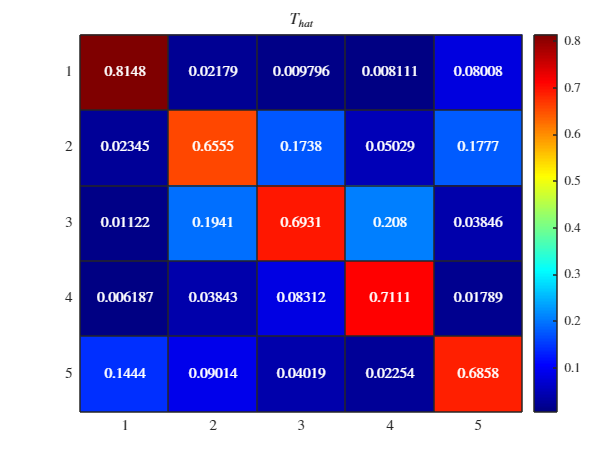


figure();
h = heatmap(T_hat, Colormap=jet());
h.Title = '$T_{hat}$';
h.Interpreter = 'latex';

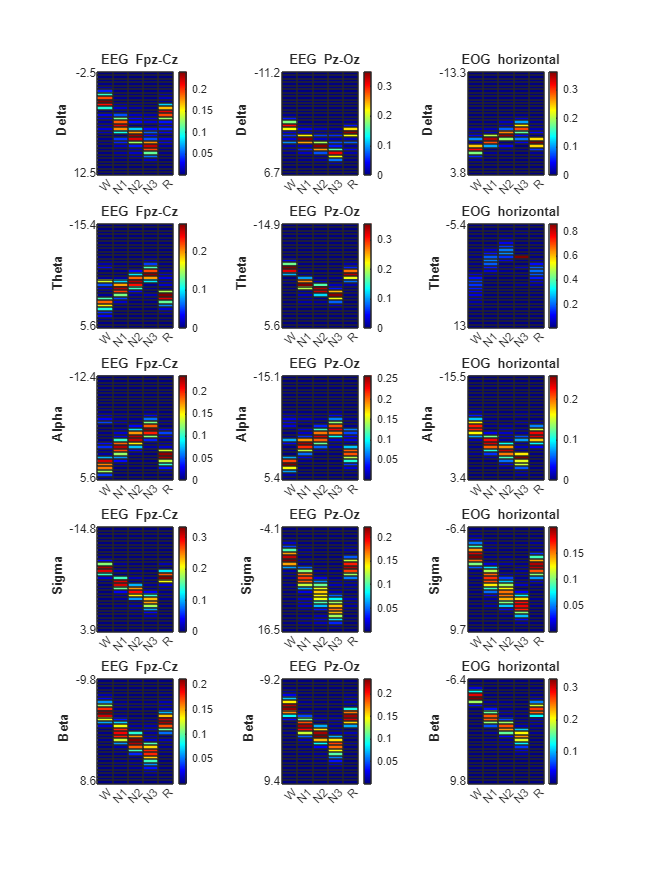


figure('Position', [10 10 1500 2000]);
num = 0;
for b = 1:nBands
    for ch = 1:nChannels
        num = num + 1;
        subplot(nBands, nChannels, num);

        h = heatmap(O_hats{num}, Colormap=jet());
        h.Title = "\bf " + info.SignalLabels{ch};
        h.YLabel = "\bf " + bandNames{b};
        h.XData = {"W", "N1", "N2", "N3", "R"};

        h.YDisplayLabels = [num2str(round(mins(num), 1)), repelem("", d-2), num2str(round(maxs(num), 1))];
    end
end


perm = [4, 5, 1, 2, 3];



T_hat = T_hat(perm, perm);

for i = 1:n
    O_hat = O_hats{i};
    O_hats{i} = O_hat(:, perm);
end

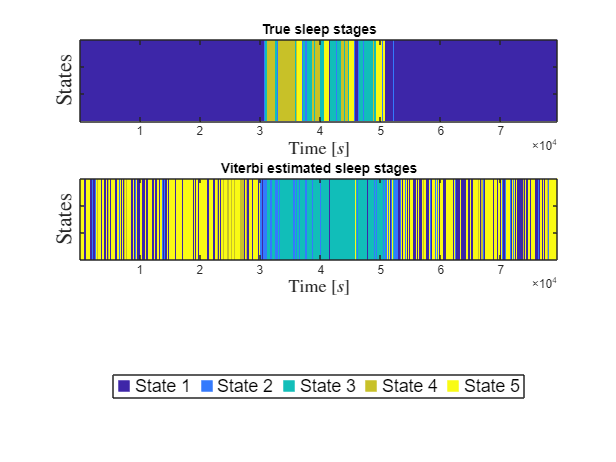


[vPath, delta] = multivariate_viterbi_algorithm(disc_seq, T_hat, O_hats, pi_hat, 0.3, 5);


% state_colors = match_states(expandedStages, vPath + 1)';
m = length(vPath);

figure();

cmap = [0,0,0; parula(k)];
colormap(cmap);

state_colors = vPath' + 1;

subplot(3, 1, 1);
imagesc(1:length(expandedStages), [0 1], expandedStages);
clim([1 k+1]);
ylabel("States", "Interpreter", "latex","FontSize",15);
set(gca,'YTickLabel',[]);
xlabel("Time [$s$]", "Interpreter", "latex","FontSize",12);
title("True sleep stages")


subplot(3, 1, 2);
imagesc(1:m, [0 1], state_colors(1:m));
clim([1 k+1]);
ylabel("States", "Interpreter", "latex","FontSize",15);
set(gca,'YTickLabel',[]);
xlabel("Time [$s$]", "Interpreter", "latex","FontSize",12);
title("Viterbi estimated sleep stages")

% --- Add legend as an invisible axes at the bottom ---
legend_ax = subplot(3, 1, 3);
axis off;  % Hide this subplot

% Create dummy handles for legend colors
hold on;
legendHandles = gobjects(k,1);
for i = 1:k
    legendHandles(i) = plot(nan, nan, 's', ...
        'MarkerFaceColor', cmap(i+1,:), ...
        'MarkerEdgeColor', cmap(i+1,:), ...
        'MarkerSize', 10);
end

legend(legendHandles, arrayfun(@(x) sprintf('State %d', x), 1:k, 'UniformOutput', false), ...
       'Orientation', 'horizontal', ...
       'Location', 'southoutside', ...
       'FontSize', 12);


score = 0;
for i = 1:length(state_colors)
    if(state_colors(i) == expandedStages(i+1))
        score = score + 1;
    end
end

score = score/length(state_colors)

score = 0.2973

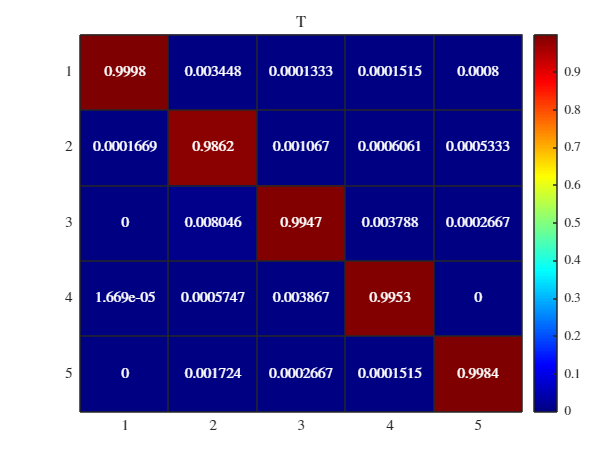

T_est = zeros(k,k);
O_est = cell(n, 1);

for i = 1:n
    [T_est_temp, O_est_temp] = hmmestimate(disc_seq(i, :), expandedStages(1:m) - 1, 'Symbols',1:d);
    T_est = T_est + (1/n) * T_est_temp';
    O_est{i} = O_est_temp';
end


figure()
h = heatmap(T_est, Colormap=jet());
h.Title = 'T';
h.Interpreter = 'latex';

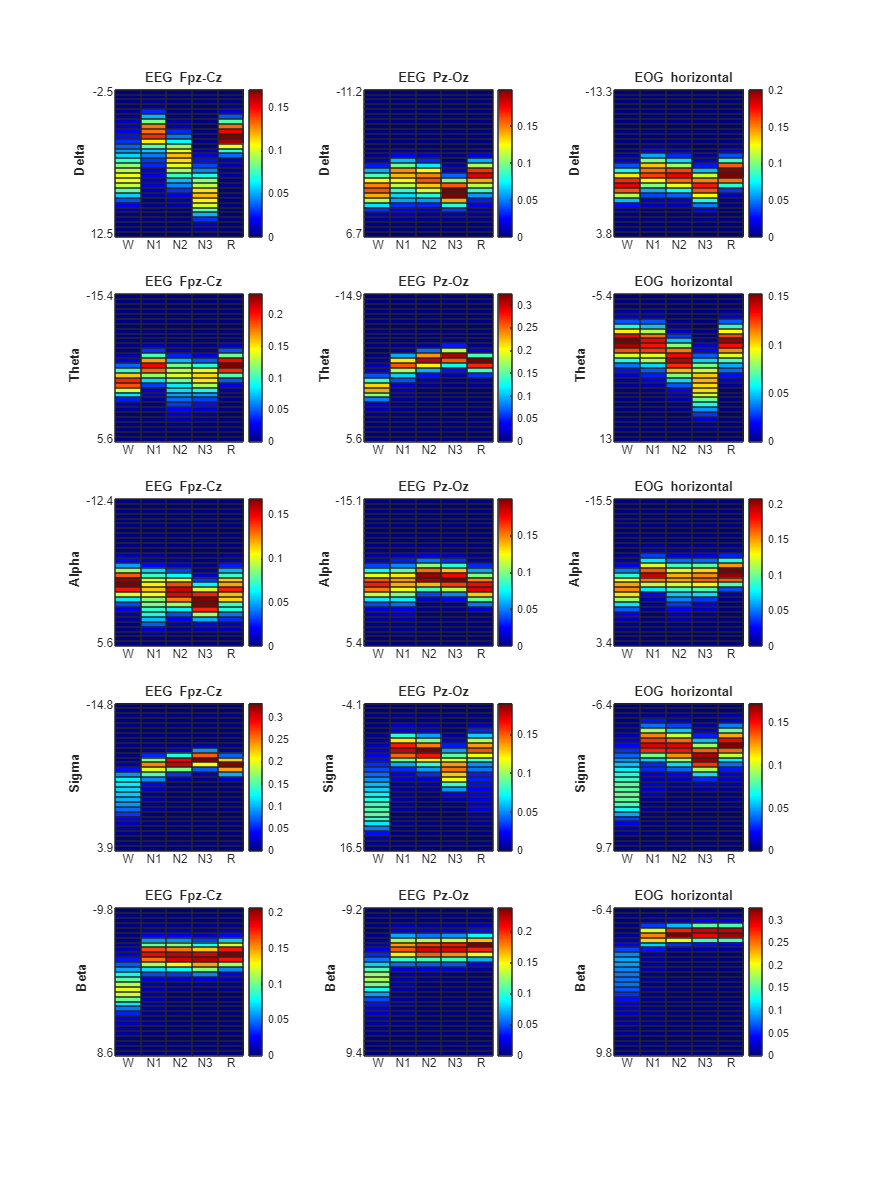

figure('Position', [10 10 1500 2000]);
num = 0;
for b = 1:nBands
    for ch = 1:nChannels
        num = num + 1;
        subplot(nBands, nChannels, num);

        h = heatmap(O_est{num}, Colormap=jet());
        h.Title = "\bf " + info.SignalLabels{ch};
        h.YLabel = "\bf " + bandNames{b};
        h.XData = {"W", "N1", "N2", "N3", "R"};

        h.YDisplayLabels = [num2str(round(mins(num), 1)), repelem("", d-2), num2str(round(maxs(num), 1))];
    end
end

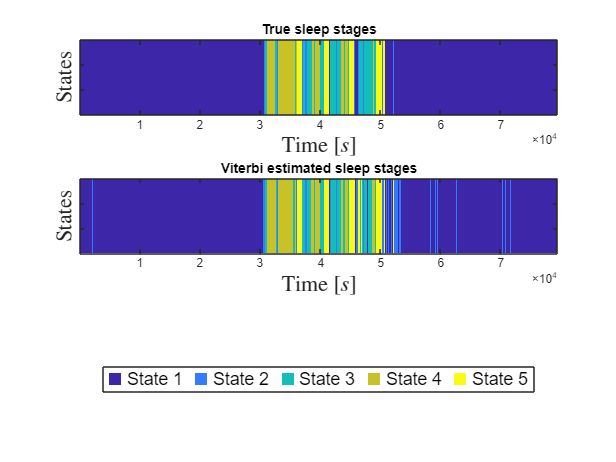



[vPath, delta] = multivariate_viterbi_algorithm(disc_seq, T_est, O_est, findStationaryDistribution(T_est')', 0.5, 0);

m = length(vPath);

figure();

cmap = [0,0,0; parula(k)];
colormap(cmap);

state_colors = vPath' + 1;



subplot(3, 1, 1);
imagesc(1:length(expandedStages), [0 1], expandedStages);
clim([1 k+1]);
ylabel("States", "Interpreter", "latex","FontSize",15);
set(gca,'YTickLabel',[]);
xlabel("Time [$s$]", "Interpreter", "latex","FontSize",15);
title("True sleep stages")


subplot(3, 1, 2);
imagesc(1:m, [0 1], state_colors(1:m));
clim([1 k+1]);
ylabel("States", "Interpreter", "latex","FontSize",15);
set(gca,'YTickLabel',[]);
xlabel("Time [$s$]", "Interpreter", "latex","FontSize",15);
title("Viterbi estimated sleep stages")

% --- Add legend as an invisible axes at the bottom ---
legend_ax = subplot(3, 1, 3);
axis off;  % Hide this subplot

% Create dummy handles for legend colors
hold on;
legendHandles = gobjects(k,1);
for i = 1:k
    legendHandles(i) = plot(nan, nan, 's', ...
        'MarkerFaceColor', cmap(i+1,:), ...
        'MarkerEdgeColor', cmap(i+1,:), ...
        'MarkerSize', 10);
end

legend(legendHandles, arrayfun(@(x) sprintf('State %d', x), 1:k, 'UniformOutput', false), ...
       'Orientation', 'horizontal', ...
       'Location', 'southoutside', ...
       'FontSize', 12);